x = linspace(1, 2);
f = @(x) x.*exp(0.5.*x) + 1.2.*x - 5;
g = @(x) 5 ./ (exp(0.5.*x) + 1.2);

plot(x, f(x))
hold on
c = punto_fijo_tabla_tol_f(f, g, 1.7, 0.0001)

    It      xi       g(xi)=xi+1      f(c)       Error 
    __    _______    __________    ________    _______

     0    1.70000     1.41257      -0.44241    0.44241
     1    1.41257     1.54969       0.22286    0.22286
     2    1.54969     1.48357      -0.10471    0.10471
     3    1.48357     1.51530       0.05089    0.05089
     4    1.51530     1.50003      -0.02433    0.02433
     5    1.50003     1.50737       0.01173    0.01173
     6    1.50737     1.50384      -0.00563    0.00563
     7    1.50384     1.50554       0.00271    0.00271
     8    1.50554     1.50472      -0.00130    0.00130
     9    1.50472     1.50511       0.00063    0.00063
    10    1.50511     1.50493      -0.00030    0.00030
    11    1.50493     1.50502       0.00014    0.00014
    12    1.50502     1.50497      -0.00007    0.00007



c = 1.5050

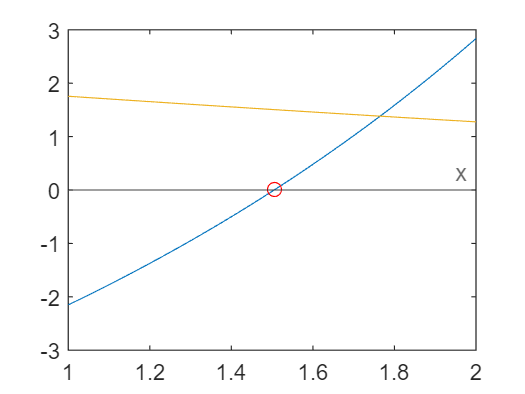

plot(c, f(c),'ro')
yline(0, '-', {'x'})
plot(x, g(x))
hold off

g1 = @(x) sin(sqrt(x))-x;
punto_fijo_tabla_tol_f(@(x) sin(sqrt(x)), g1, 0.6, 0.0001)